## Mechazilla's catching system - LBC project

clear all
close all
clc

par = get_params();

b = par.rock.b;
h = par.rock.h;
m = par.rock.m;
g = par.rock.g;

Fc_max = par.rock.Fc_max;
Fl_max = par.rock.Fl_max;
Fr_max = par.rock.Fr_max;

py0_min = par.gen.py_min;
py0_max = par.gen.py_max;
theta0_max = par.gen.theta_max;
theta0_min = par.gen.theta_min;

px_max = par.sym.px_max;
py_min = par.sym.py_min;
py_max = par.sym.py_max;
theta_max = par.sym.theta_max;
py_dot_max = par.sym.py_dot_max;
theta_dot_max = par.sym.theta_dot_max;
py_target = par.env.target_py;
py_max_dist = py_max-py_target;
py_max_dist_2 = py_target-py_min;

py_catch_min = par.sym.py_catch_min;
py_catch_max = par.sym.py_catch_max;

py_target_min = par.env.py_target_min;
py_target_max = par.env.py_target_max;

global py_edges theta_edges py_dot_edges theta_dot_edges;


py_edges = [-inf, 0, 20, 30, 33, 34, 35, 36, 37, 40, 50, 75, 100, 130, 160, 200, inf];
theta_edges = deg2rad([-inf, -15, -10, -5, -2, -1, 1, 2, 5, 10, 15, inf]);
py_dot_edges = [-inf, -50, -40, -30, -25, -20, -15, -10, -5, -2, 0, 2, 5, 10, inf];
theta_dot_edges = [-inf, -0.5, 0, 0.5, inf];

num_py = length(py_edges) - 1;
num_theta = length(theta_edges) - 1;
num_py_dot = length(py_dot_edges) - 1;
num_theta_dot = length(theta_dot_edges) - 1;

% Q-LEARNING

N = 50000;
T = 200;
Ts = 0.1;

U = [0,         0,          0;
     Fc_max,    0,          0;
     0,         Fl_max,     0;
     0,         0,          Fr_max;
     Fc_max,    Fl_max,     0;
     Fc_max,    0,          Fr_max];

num_U = size(U,1);

Q_QL = zeros(num_py, num_theta, num_py_dot, num_theta_dot, num_U);

% learning rate
alph = 0.01;

% discount factor
gamm = 0.99;

epsilon = 1.0; 
epsilon_min = 0.01;
decay = 0.9995;

% G is the cumulative reward
G=zeros(N,T);

final_G_QL = zeros(N,1);

Q_r = diag([1/(py_max_dist^2); 1/(theta_max^2); 1/(py_dot_max^2); 1/(theta_dot_max^2)]);


tic

for i=1:N

    x0=[py0_min+(py0_max-py0_min)*rand(); theta0_min+(theta0_max-theta0_min)*rand(); 0; 0];
    
    epsilon = max(epsilon_min, epsilon * decay);

    % x_sol contains the results of the ode45
    x_sol = zeros(4,T+1);
    x_sol(:,1) = x0;

    % flag if we exit from the constraints
    exit = 0;
    
    for j = 1:T
        % discretize x(k)
        x_sol_index = discretize_custom(x_sol(:,j));
        x_curr = x_sol(:,j);

        Q_values = Q_QL(x_sol_index(1),x_sol_index(2), x_sol_index(3), x_sol_index(4),:);

        % apply epsilon-greedy policy and return u_i the index of the input
        % to apply
        u_i = epsilon_greedy_policy(Q_values, epsilon);
        u = U(u_i, :);

        % compute dx/dt=f(x,t)
        [t,dx] = ode45(@(t,x) solution(t,x,m,b,h,g,u), [(j-1)*Ts j*Ts], x_sol(:,j));
    
        %update x(k)=x(k+1)
        x_sol(:,j+1) = dx(end,:)';

        % observe x(k+1) and r(k+1)
        x_next = x_sol(:,j+1);
        x_next_index = discretize_custom(x_next);
       
        x_reward = [x_next(1)-py_target; x_next(2); x_next(3); x_next(4)];
        x_prev_reward = [x_curr(1)-py_target; x_curr(2); x_curr(3); x_curr(4)];
        phi_next = -sqrt(x_reward' * Q_r * x_reward); 
        phi_curr = -sqrt(x_prev_reward' * Q_r * x_prev_reward);

        % r = gamma*phi(x(k+1)) - phi(x(k))
        r_dense = gamm*phi_next - phi_curr; 
        
        % time increase penalty
        r = r_dense - 0.1;


        if (x_next(1)>=py_catch_min && x_next(1)<=py_catch_max && abs(x_next(2))<=deg2rad(5) && abs(x_next(3))<5 && abs(x_next(4))<0.5) 
            r = 2000;
            catched = 1;
            exit=1;
        end


        if (x_next(1)<=py_min || x_next(1)>py_max || abs(x_next(2))>theta_max || abs(x_next(3))>py_dot_max || abs(x_next(4))>theta_dot_max)
            r = -1000;
            exit = 1;
        end

        Q_xu = Q_QL(x_sol_index(1),x_sol_index(2), x_sol_index(3), x_sol_index(4), u_i);

        target = r + gamm * max(Q_QL(x_next_index(1), x_next_index(2), x_next_index(3), x_next_index(4), :));

        % update Q(x(k),u(k)) 
        Q_xu_update = Q_xu + alph*(target-Q_xu);
        Q_QL(x_sol_index(1),x_sol_index(2),x_sol_index(3), x_sol_index(4), u_i) = Q_xu_update;
        
        %cumulative reward
        G(j,i) = (gamm^(j-1))*r;

        if(exit==1)
            break
        end
    end

    
end

for i=1:N
    final_G_QL(i)=sum(G(:,i));
end

toc

Elapsed time is 1023.265196 seconds.


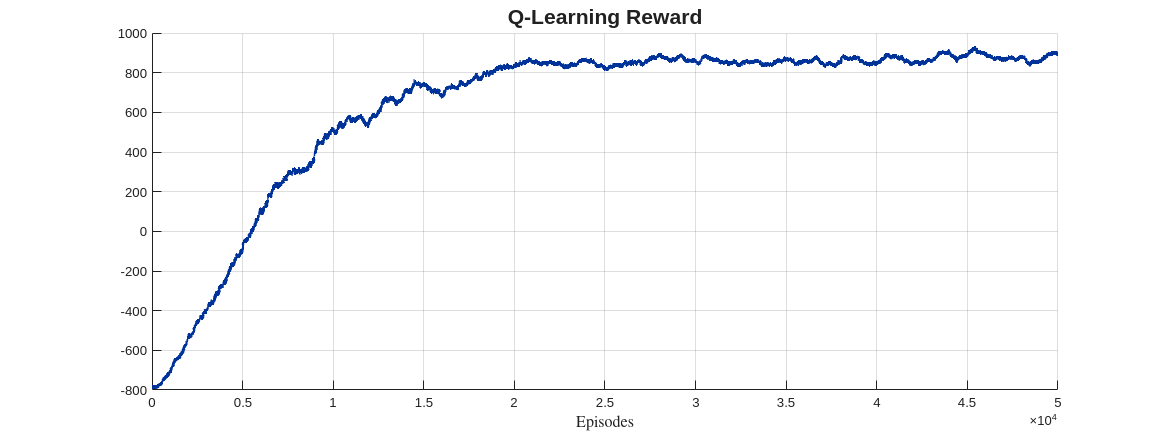

smoothed_data_QL = movmean(final_G_QL, 1000);

figure('Name', 'Q-Learning Reward','Units','pixels','Position',[1,1,1280,480]);
hold on
plot(smoothed_data_QL, 'Color', [0, 0.2, 0.6], 'LineWidth', 2.5);
title('Q-Learning Reward', 'FontSize',16)
grid on;
xlabel('Episodes', 'Interpreter','latex','FontSize',12);

## TEST LOOP

N_test = 10;

for i = 1:N_test

    x0=[py0_min+(py0_max-py0_min)*rand(); theta0_min+(theta0_max-theta0_min)*rand(); 0; 0];
    x_test = x0;
    catched = false;
    
    for j = 1:T
        idx = discretize_custom(x_test);
        
        [~, u_i] = max(Q_QL(idx(1), idx(2), idx(3), idx(4), :));
        u_cmd = U(u_i, :);
        
        [~, dx] = ode45(@(t,x) solution(t,x,m,b,h,g,u_cmd), [0 Ts], x_test);
        x_test = dx(end,:)';
        
        % Check Catch
        if (x_test(1) >= py_catch_min && x_test(1) <= py_catch_max && abs(x_test(2))<=theta_max && abs(x_test(3))<=5 && abs(x_test(4))<=0.1)
            catched = true;
            break;
        end
        
        if x_test(1) <= 0, break; end
    end
    
    disp("-------------------");
    if catched
        disp("Preso!")
    else
        disp("Non preso :(");
        fprintf("T finale = %f", j*Ts);
        fprintf("Posizione y: %f \nAngolo theta: %f \nVelocità y: %f \nVelocità theta: %f", x_test(1), deg2rad(x_test(2)), x_test(3), x_test(4));
    end
end        

-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


N_test = 100;
N_passed = 0;
N_failed = 0;

for i = 1:N_test

    x0=[py0_min+(py0_max-py0_min)*rand(); theta0_min+(theta0_max-theta0_min)*rand(); 0; 0];
    x_test = x0;
    catched = false;
    
    for j = 1:T
        idx = discretize_custom(x_test);
        
        [~, u_i] = max(Q_QL(idx(1), idx(2), idx(3), idx(4), :));
        u_cmd = U(u_i, :);
        
        [~, dx] = ode45(@(t,x) solution(t,x,m,b,h,g,u_cmd), [0 Ts], x_test);
        x_test = dx(end,:)';
        
        % Check Catch
        if (x_test(1) >= py_catch_min && x_test(1) <= py_catch_max && abs(x_test(2))<=theta_max && abs(x_test(3))<=5 && abs(x_test(4))<=0.1)
            catched = true;
            break;
        end
        
        if x_test(1) <= 0, break; end
    end
    
    if catched, N_passed = N_passed + 1; else, N_failed = N_failed + 1; end
end

fprintf("Passed test: %d\n", N_passed);

Passed test: 98


fprintf("Failed test: %d\n", N_failed);

Failed test: 2


## PLOT ESEMPIO SINGOLO

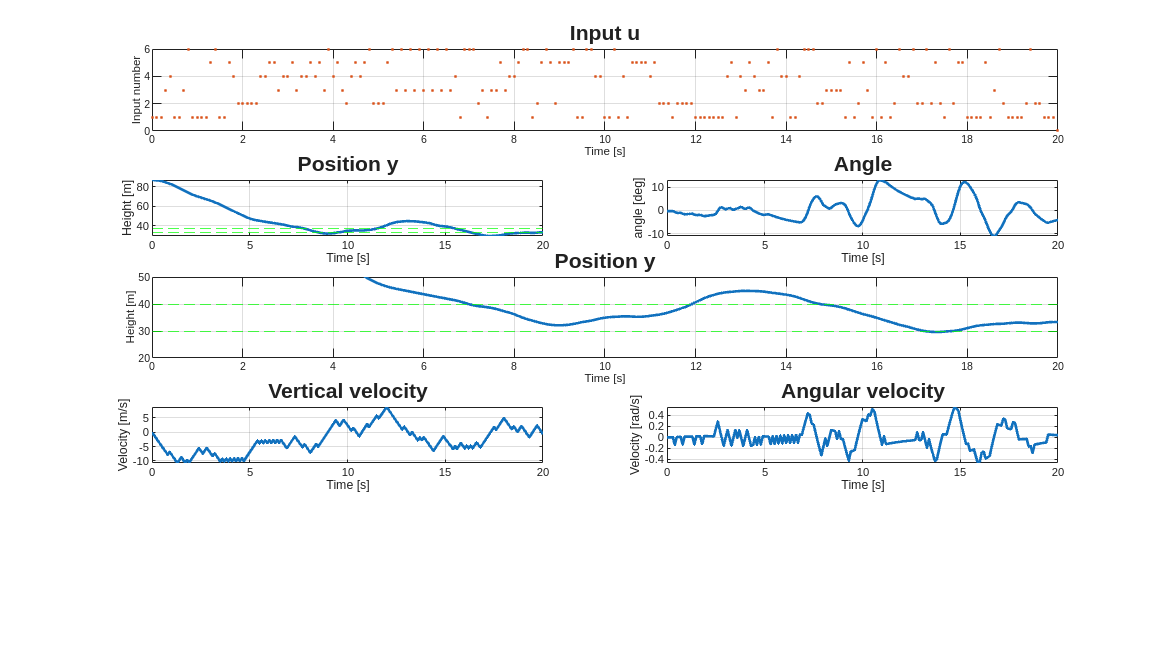

x0=[py0_min+(py0_max-py0_min)*rand(); theta0_min+(theta0_max-theta0_min)*rand(); 0; 0];
x_sol = zeros(4,T+1);
x_sol(:,1) = x0;
u_plot = zeros(T,1);

for j = 1:T
    idx = discretize_custom(x_sol(:,j));
    [~, u_i] = max(Q_QL(idx(1), idx(2), idx(3), idx(4), :));
    u_plot(j) = u_i;
    u_cmd = U(u_i, :);
    
    [~, dx] = ode45(@(t,x) solution(t,x,m,b,h,g,u_cmd), [0 Ts], x_sol(:,j));
    x_sol(:,j+1) = dx(end,:)';
    
    if x_sol(1,j+1) <= 0 || (x_sol(1) >= py_catch_min && x_sol(1) <= py_catch_max && abs(x_sol(2))<=theta_max && abs(x_sol(3))<=5 && abs(x_sol(4))<=0.1)
        break; 
    end
end
T_final = j;
u_plot=[u_plot;0];

t = 0:Ts:T_final*Ts;
figure('Name', 'Example', 'Units', 'normalized', 'Position', [0.1 0.1 1 1]);
subplot(5,2,1:2)
stairs(t, u_plot(1:length(t)), 'k.', 'LineWidth', 2, 'Color', [0.85 0.32 0.1])
title('Input u', 'FontSize',16);
grid on
ylabel('Input number');
xlabel('Time [s]');
axis tight;

subplot(5,2,3)
plot(t, x_sol(1,1:length(t)), 'LineWidth', 2)
title('Position y', 'FontSize',16);
grid on
hold on
ylim([0, 250]);
yline(py_catch_max, '--g');
yline(py_catch_min, '--g')
ylabel('Height [m]');
xlabel('Time [s]')
axis tight;

subplot(5,2,4)
plot(t, rad2deg(x_sol(2,1:length(t))), 'LineWidth', 2)
title('Angle', 'FontSize',16);
grid on
ylabel('angle [deg]');
xlabel('Time [s]')
axis tight;

subplot(5,2,5:6)
plot(t, x_sol(1,1:length(t)), 'LineWidth', 2)
title('Position y', 'FontSize',16);
grid on
hold on
ylim([20, 50]);
yline(py_target_max, '--g');
yline(py_target_min, '--g')
ylabel('Height [m]');
xlabel('Time [s]')
xlim([0, t(end)]);

subplot(5,2,7)
plot(t, x_sol(3,1:length(t)), 'LineWidth', 2)
title('Vertical velocity', 'FontSize',16);
grid on
ylabel('Velocity [m/s]');
xlabel('Time [s]')
axis tight;

subplot(5,2,8)
plot(t, x_sol(4,1:length(t)), 'LineWidth', 2)
title('Angular velocity', 'FontSize',16);
grid on
ylabel('Velocity [rad/s]');
xlabel('Time [s]')
axis tight;

Q_SARSA = zeros(num_py, num_theta, num_py_dot, num_theta_dot, num_U);

epsilon = 1.0; 

% G is the cumulative reward
G=zeros(N,T);

final_G_SARSA = zeros(N,1);


tic

for i=1:N

    x0=[py0_min+(py0_max-py0_min)*rand(); theta0_min+(theta0_max-theta0_min)*rand(); 0; 0];
    
    epsilon = max(epsilon_min, epsilon * decay);

    % x_sol contains the results of the ode45
    x_sol = zeros(4,T+1);
    x_sol(:,1) = x0;

    % flag if we exit from the constraints
    exit = 0;

    x_sol_index = discretize_custom(x_sol(:,1));
        

    Q_values = Q_SARSA(x_sol_index(1),x_sol_index(2), x_sol_index(3), x_sol_index(4),:);

        
    u_i = epsilon_greedy_policy(Q_values, epsilon);
    u = U(u_i, :);
    
    for j = 1:T
        % discretize x(k)
        x_sol_index = discretize_custom(x_sol(:,j));
        x_curr = x_sol(:,j);

        % compute dx/dt=f(x,t)
        [t,dx] = ode45(@(t,x) solution(t,x,m,b,h,g,u), [(j-1)*Ts j*Ts], x_sol(:,j));
    
        %update x(k)=x(k+1)
        x_sol(:,j+1) = dx(end,:)';

        % observe x(k+1) and r(k+1)
        x_next = x_sol(:,j+1);
        x_next_index = discretize_custom(x_next);

        u_next = epsilon_greedy_policy(Q_SARSA(x_next_index(1),x_next_index(2),x_next_index(3),x_next_index(4),:), epsilon);

        x_reward = [x_next(1)-py_target; x_next(2); x_next(3); x_next(4)];
        x_prev_reward = [x_curr(1)-py_target; x_curr(2); x_curr(3); x_curr(4)];
        phi_next = -sqrt(x_reward' * Q_r * x_reward); 
        phi_curr = -sqrt(x_prev_reward' * Q_r * x_prev_reward);

        % r_shaping = gamma * phi(x(k+1)) - phi(x(k))
        r_dense = gamm * phi_next - phi_curr; 

        r = r_dense - 0.1;


        if (x_next(1)>=py_catch_min && x_next(1)<=py_catch_max && abs(x_next(2))<=deg2rad(5) && abs(x_next(3))<5 && abs(x_next(4))<0.5) 
            r = 2000;
            catched = 1;
            exit=1;
        end


        if (x_next(1)<=py_min || x_next(1)>py_max || abs(x_next(2))>theta_max || abs(x_next(3))>py_dot_max || abs(x_next(4))>theta_dot_max)
            r = -1000;
            exit = 1;
        end

        Q_xu = Q_SARSA(x_sol_index(1),x_sol_index(2), x_sol_index(3), x_sol_index(4), u_i);

        target = r + gamm * Q_SARSA(x_next_index(1), x_next_index(2), x_next_index(3), x_next_index(4), u_next);

        % update Q(x(k),u(k)) 
        Q_xu_update = Q_xu + alph*(target-Q_xu);
        Q_SARSA(x_sol_index(1),x_sol_index(2),x_sol_index(3), x_sol_index(4), u_i) = Q_xu_update;
        
        %cumulative reward
        G(j,i) = (gamm^(j-1))*r;

        u_i = u_next;
        u = U(u_i,:);

        if(exit==1)
            break
        end
    end

    
end

for i=1:N
    final_G_SARSA(i)=sum(G(:,i));
end

toc

Elapsed time is 1111.852330 seconds.


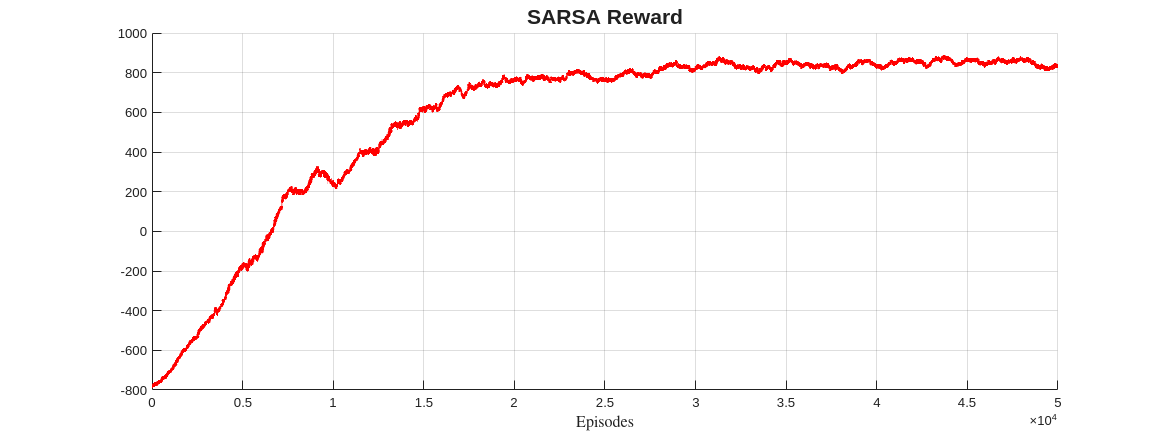

smoothed_data_SARSA = movmean(final_G_SARSA, 1000);

figure('Name', 'SARSA Reward','Units','pixels','Position',[1,1,1280,480]);
hold on
plot(smoothed_data_SARSA, 'Color', 'r', 'LineWidth', 2.5);
title('SARSA Reward', 'FontSize',16)
grid on;
xlabel('Episodes', 'Interpreter','latex','FontSize',12);

## TEST LOOP

N_test = 10;

for i = 1:N_test

    x0=[py0_min+(py0_max-py0_min)*rand(); theta0_min+(theta0_max-theta0_min)*rand(); 0; 0];
    x_test = x0;
    catched = false;
    
    for j = 1:T
        idx = discretize_custom(x_test);
        
        [~, u_i] = max(Q_SARSA(idx(1), idx(2), idx(3), idx(4), :));
        u_cmd = U(u_i, :);
        
        [~, dx] = ode45(@(t,x) solution(t,x,m,b,h,g,u_cmd), [0 Ts], x_test);
        x_test = dx(end,:)';
        
        % Check Catch
        if (x_test(1) >= py_catch_min && x_test(1) <= py_catch_max && abs(x_test(2))<=theta_max && abs(x_test(3))<=5 && abs(x_test(4))<=0.1)
            catched = true;
            break;
        end
        
        if x_test(1) <= 0, break; end
    end
    
    disp("-------------------");
    if catched
        disp("Preso!")
    else
        disp("Non preso :(");
        fprintf("T finale = %f", j*Ts);
        fprintf("Posizione y: %f \nAngolo theta: %f \nVelocità y: %f \nVelocità theta: %f", x_test(1), deg2rad(x_test(2)), x_test(3), x_test(4));
    end
end

-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


-------------------


Preso!


N_test = 100;
N_passed = 0;
N_failed = 0;

for i = 1:N_test

    x0=[py0_min+(py0_max-py0_min)*rand(); theta0_min+(theta0_max-theta0_min)*rand(); 0; 0];
    x_test = x0;
    catched = false;
    
    for j = 1:T
        idx = discretize_custom(x_test);
        
        [~, u_i] = max(Q_SARSA(idx(1), idx(2), idx(3), idx(4), :));
        u_cmd = U(u_i, :);
        
        [~, dx] = ode45(@(t,x) solution(t,x,m,b,h,g,u_cmd), [0 Ts], x_test);
        x_test = dx(end,:)';
        
        % Check Catch
        if (x_test(1) >= py_catch_min && x_test(1) <= py_catch_max && abs(x_test(2))<=theta_max && abs(x_test(3))<=5 && abs(x_test(4))<=0.1)
            catched = true;
            break;
        end
        
        if x_test(1) <= 0, break; end
    end
    
    if catched, N_passed = N_passed + 1; else, N_failed = N_failed + 1; end
end

fprintf("Passed test: %d\n", N_passed);

Passed test: 100


fprintf("Failed test: %d\n", N_failed);

Failed test: 0


## PLOT ESEMPIO SINGOLO

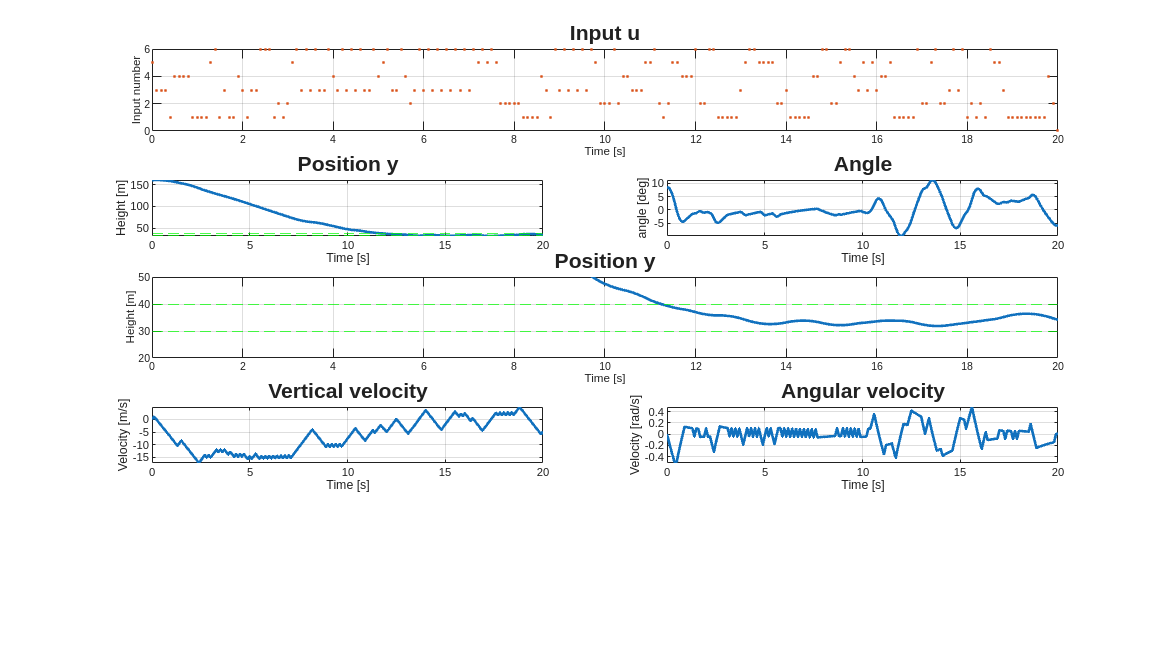

x_sol = zeros(4,T+1);
x0=[py0_min+(py0_max-py0_min)*rand(); theta0_min+(theta0_max-theta0_min)*rand(); 0; 0];
x_sol(:,1) = x0;
u_plot = zeros(T,1);

for j = 1:T
    idx = discretize_custom(x_sol(:,j));
    [~, u_i] = max(Q_SARSA(idx(1), idx(2), idx(3), idx(4), :));
    u_plot(j) = u_i;
    u_cmd = U(u_i, :);
    
    [~, dx] = ode45(@(t,x) solution(t,x,m,b,h,g,u_cmd), [0 Ts], x_sol(:,j));
    x_sol(:,j+1) = dx(end,:)';
    
    if x_sol(1,j+1) <= 0 || (x_sol(1) >= py_catch_min && x_sol(1) <= py_catch_max && abs(x_sol(2))<=theta_max && abs(x_sol(3))<=5 && abs(x_sol(4))<=0.1)
        break; 
    end
end
T_final = j;
u_plot=[u_plot;0];

t = 0:Ts:T_final*Ts;
figure('Name', 'Example', 'Units', 'normalized', 'Position', [0.1 0.1 1 1]);
subplot(5,2,1:2)
stairs(t, u_plot(1:length(t)), 'k.', 'LineWidth', 2, 'Color', [0.85 0.32 0.1])
title('Input u', 'FontSize',16);
grid on
ylabel('Input number');
xlabel('Time [s]');
axis tight;

subplot(5,2,3)
plot(t, x_sol(1,1:length(t)), 'LineWidth', 2)
title('Position y', 'FontSize',16);
grid on
hold on
ylim([0, 250]);
yline(py_catch_max, '--g');
yline(py_catch_min, '--g')
ylabel('Height [m]');
xlabel('Time [s]')
axis tight;

subplot(5,2,4)
plot(t, rad2deg(x_sol(2,1:length(t))), 'LineWidth', 2)
title('Angle', 'FontSize',16);
grid on
ylabel('angle [deg]');
xlabel('Time [s]')
axis tight;

subplot(5,2,5:6)
plot(t, x_sol(1,1:length(t)), 'LineWidth', 2)
title('Position y', 'FontSize',16);
grid on
hold on
ylim([20, 50]);
yline(py_target_max, '--g');
yline(py_target_min, '--g')
ylabel('Height [m]');
xlabel('Time [s]')
xlim([0, t(end)]);

subplot(5,2,7)
plot(t, x_sol(3,1:length(t)), 'LineWidth', 2)
title('Vertical velocity', 'FontSize',16);
grid on
ylabel('Velocity [m/s]');
xlabel('Time [s]')
axis tight;

subplot(5,2,8)
plot(t, x_sol(4,1:length(t)), 'LineWidth', 2)
title('Angular velocity', 'FontSize',16);
grid on
ylabel('Velocity [rad/s]');
xlabel('Time [s]')
axis tight;

%% FUNCTIONS

% function for ode45
function dxdt = solution(t, x, m, b, h, g, u)
  dxdt = zeros(4,1);

  Fc = u(1);
  Fl = u(2);
  Fr = u(3);

  dxdt(1) = x(3);
  dxdt(2) = x(4);
  dxdt(3) = 1/m*((Fl-Fr)*sin(x(2))+Fc*cos(x(2)))-g;
  dxdt(4) = ( (Fr - Fl) * (h/2) - (20000 * x(4)) ) / ( (m * (b^2 + h^2)) / 12 );
end

function x_disc = discretize_custom(x)
    x_disc = zeros(4,1);

    global py_edges theta_edges py_dot_edges theta_dot_edges;
    
    x_disc(1) = discretize(x(1), py_edges);
    x_disc(2) = discretize(x(2), theta_edges);
    x_disc(3) = discretize(x(3), py_dot_edges);
    x_disc(4) = discretize(x(4), theta_dot_edges);
end

function pi_i = epsilon_greedy_policy(Qx, epsilon)
    p = rand();
    if (p<epsilon) 
        pi_i = randi(length(Qx));
    else
        [~, pi_i] = max(Qx);
    end
end

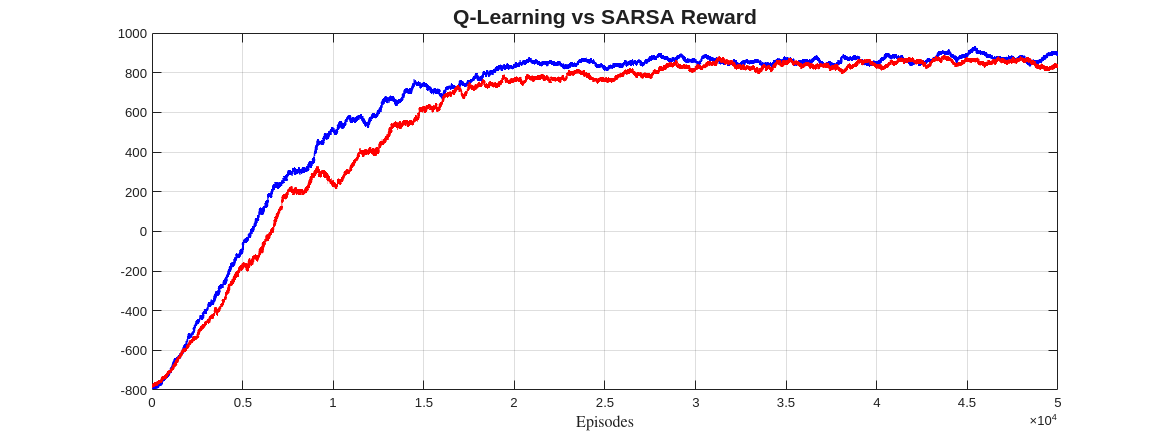

figure('Name', 'SARSA Reward','Units','pixels','Position',[1,1,1280,480]);
plot(smoothed_data_QL, 'Color', 'b', 'LineWidth', 2.5);
hold on
plot(smoothed_data_SARSA, 'Color', 'r', 'LineWidth', 2.5);
title('Q-Learning vs SARSA Reward', 'FontSize',16)
grid on;
xlabel('Episodes', 'Interpreter','latex','FontSize',12);